**a**

eta = v_r / v_b

eta > 1  : reka je hitrejša od čolna

eta == 1 : reka in čoln sta enako hitra

eta < 1  : čoln je hitrejši od reke

**b**

syms alpha
L = 1;

d_alpha = (L * cos(alpha) / sin(alpha)) + (L * sym('eta') / sin(alpha));
d_alpha_diff = diff(d_alpha, alpha);

d_alpha_diff_eta1_5 = subs(d_alpha_diff, 'eta', 1.5);
alpha_sol_eta1_5 = solve(d_alpha_diff_eta1_5 == 0, alpha);
optimal_angle_eta1_5 = eval(alpha_sol_eta1_5);
d_alpha_diff_eta2_0 = subs(d_alpha_diff, 'eta', 2.0);
alpha_sol_eta2_0 = solve(d_alpha_diff_eta2_0 == 0, alpha);
optimal_angle_eta2_0 = eval(alpha_sol_eta2_0);
d_alpha_diff_eta2_5 = subs(d_alpha_diff, 'eta', 2.5);
alpha_sol_eta2_5 = solve(d_alpha_diff_eta2_5 == 0, alpha);
optimal_angle_eta2_5 = eval(alpha_sol_eta2_5);
d_alpha_diff_eta3_0 = subs(d_alpha_diff, 'eta', 3.0);
alpha_sol_eta3_0 = solve(d_alpha_diff_eta3_0 == 0, alpha);
optimal_angle_eta3_0 = eval(alpha_sol_eta3_0);


Optimal angles in radians:


disp(num2str(optimal_angle_eta1_5))

3.9827
2.3005


disp(num2str(optimal_angle_eta2_0))

-2.0944
 2.0944


disp(num2str(optimal_angle_eta2_5))

4.3009
1.9823


disp(num2str(optimal_angle_eta3_0))

4.3726
1.9106


**c**

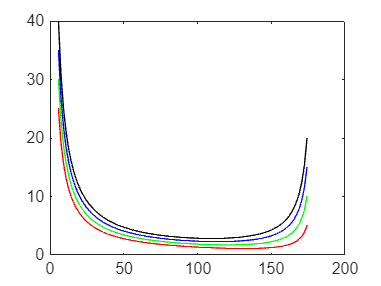

alpha_vals = linspace(0.1, pi - 0.1, 100);
alpha_vals_deg = rad2deg(alpha_vals);
d_alpha_eta1_5 = subs(d_alpha, 'eta', 1.5);
d_vals_eta1_5 = eval(subs(d_alpha_eta1_5, alpha, alpha_vals));
d_alpha_eta2_0 = subs(d_alpha, 'eta', 2.0);
d_vals_eta2_0 = eval(subs(d_alpha_eta2_0, alpha, alpha_vals));
d_alpha_eta2_5 = subs(d_alpha, 'eta', 2.5);
d_vals_eta2_5 = eval(subs(d_alpha_eta2_5, alpha, alpha_vals));
d_alpha_eta3_0 = subs(d_alpha, 'eta', 3.0);
d_vals_eta3_0 = eval(subs(d_alpha_eta3_0, alpha, alpha_vals));

figure;
plot(alpha_vals_deg, d_vals_eta1_5, 'r');
hold on;
plot(alpha_vals_deg, d_vals_eta2_0, 'g');
plot(alpha_vals_deg, d_vals_eta2_5, 'b');
plot(alpha_vals_deg, d_vals_eta3_0, 'k');
hold off;

**d**

d_alpha_eta2 = subs(d_alpha, 'eta', 2);
alpha_val = deg2rad(120);
distance_eta2_alpha120 = eval(subs(d_alpha_eta2, alpha, alpha_val));
disp(num2str(distance_eta2_alpha120))

1.7321
